# Finding Blueberry Edges

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code imports and displays an image of blueberries.

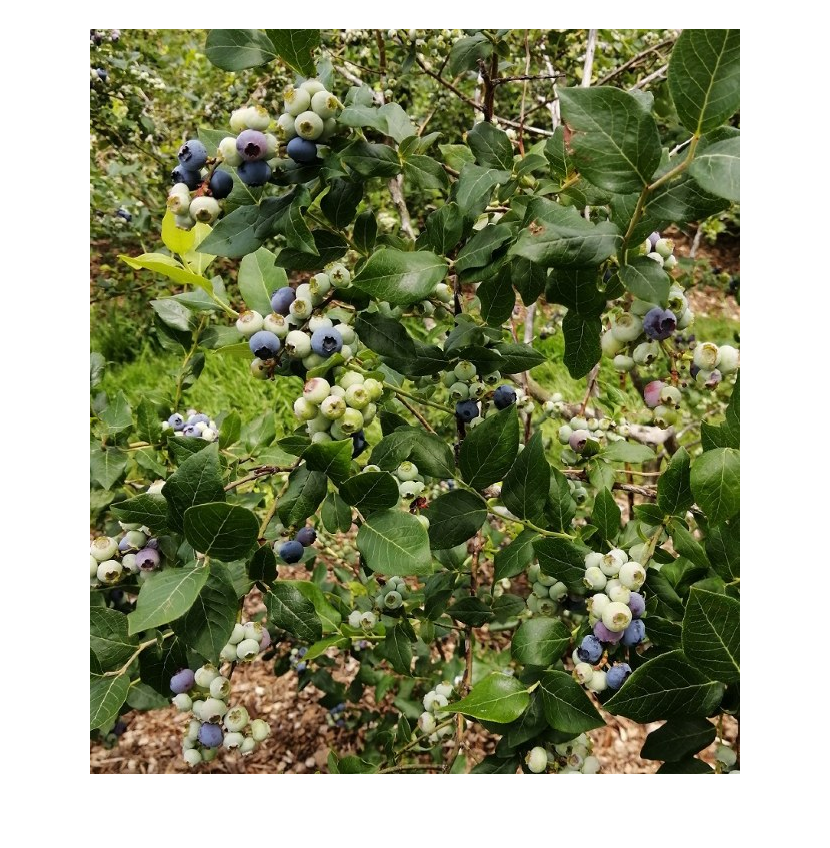

berries = imread("./images/blueberries.jpg");
imshow(berries)

This code detects edges using the default Sobel method.

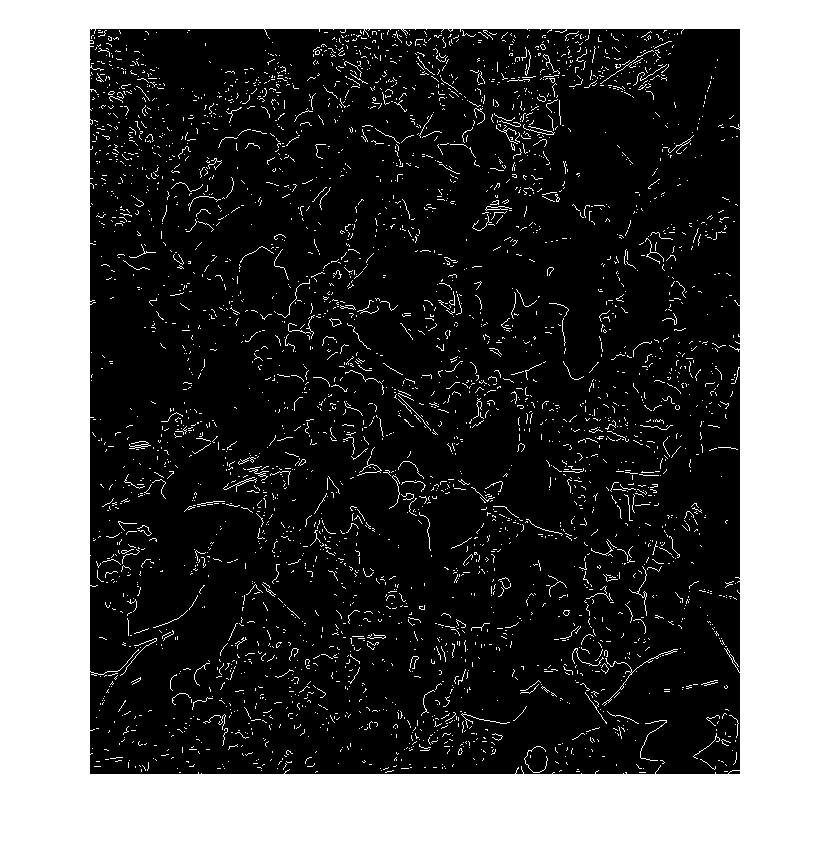

gs = im2gray(berries);
defaultEdges = edge(gs);
imshow(defaultEdges)

This code imports the pre-made binary mask, created using HSV thresholding and cleaned with morphological operations.

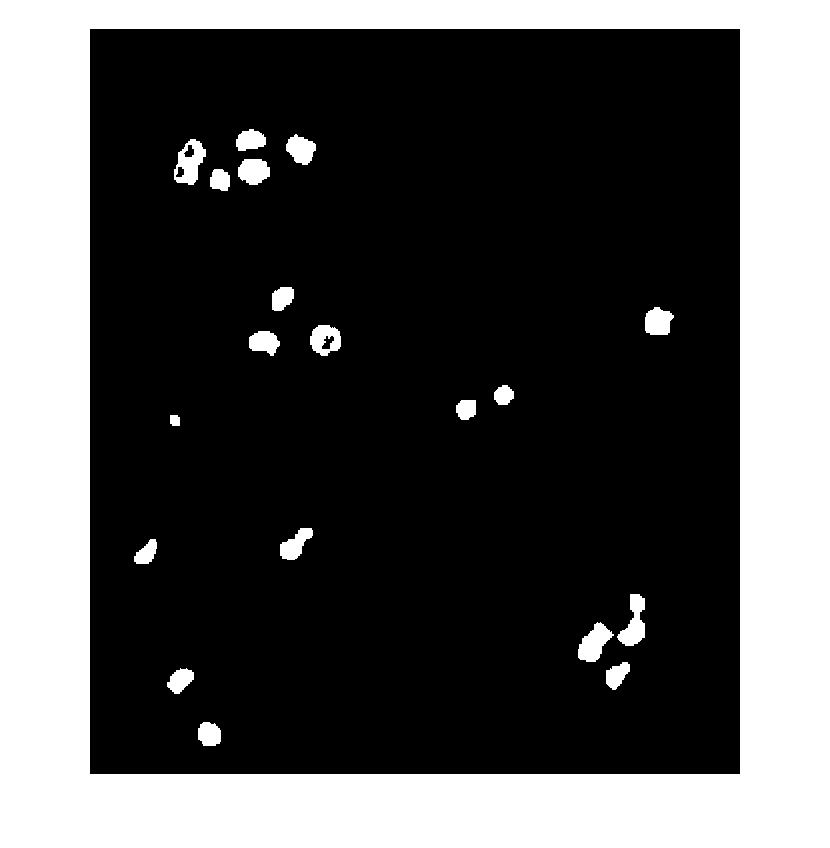

BW = imread("./images/blueberries_BW.jpg");
BW = imbinarize(BW);
imshow(BW) 

## Task 1 & 3

There are many objects in the image of blueberries: leaves, ground cover, unripe blueberries, and ripe blueberries. If you use the edge function without any preprocessing, the result is a bit of a mess. 

On the other hand, if you threshold and binarize the image first, you can obtain clean edges of just the ripe blueberries. We've loaded a cleaned binary mask into `BW`. You can find the edges of connected objects in the binary image using `bwboundaries`.

`boundaries` `=` `bwboundaries``(``BW``)`

The output is a cell array where each element contains the boundary of a connected component.

Did you notice that three of the blueberries had small holes that were detected by `bwboundaries`?

That happened because, by default, `bwboundaries` finds boundaries of connected regions of 1s (foreground) and 0s (background). Sometimes, foreground regions can have areas of background inside of them, forming *holes*. To remove the holes, add the `"noholes"` option.

`boundaries` `=` `bwboundaries``(``BW``,``"noholes"``)`.

B = bwboundaries(BW, "noholes")

B = 19×1 cell array
    { 78×2 double}
    { 83×2 double}
    { 35×2 double}
    {130×2 double}
    { 78×2 double}
    { 71×2 double}
    { 88×2 double}
    { 98×2 double}
    { 91×2 double}
    { 78×2 double}
    {108×2 double}
    { 95×2 double}
    {102×2 double}
    { 68×2 double}
    { 63×2 double}
    {118×2 double}


## Task 2

We can be certain that `bwboundaries` found the edges of the connected objects in the binary mask, but are they the edges of ripe blueberries? You can find out by visualizing the boundaries on top of the original image.

`visboundaries``(``boundaries``)`

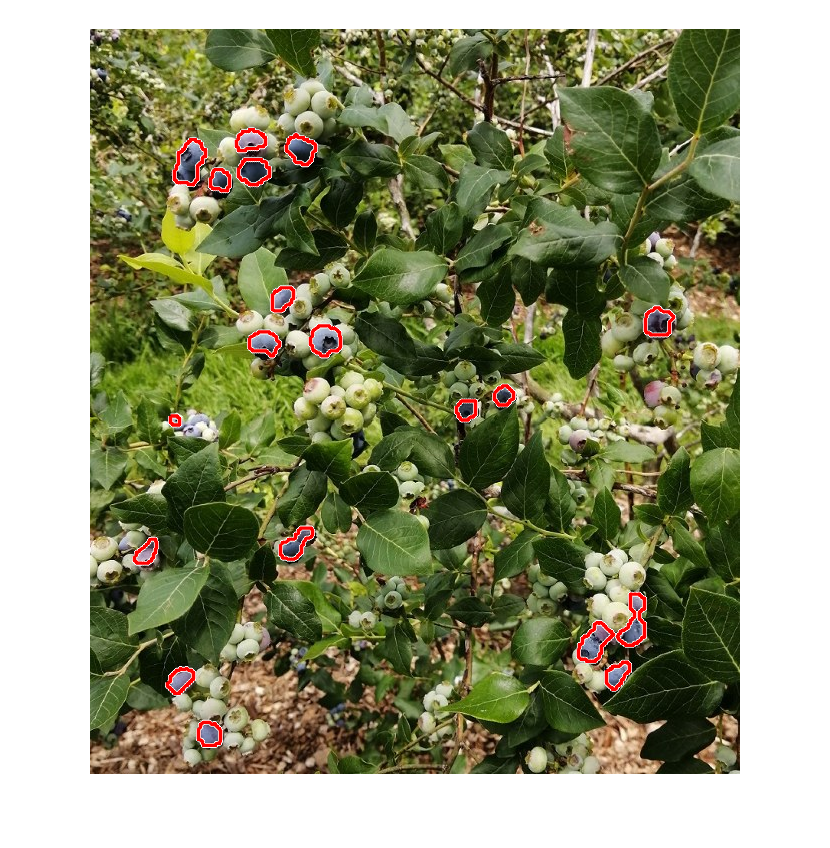

imshow(berries)
hold on
visboundaries(B)
hold off